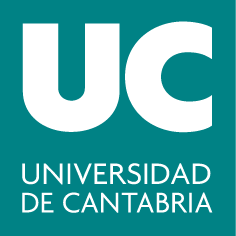

***Grados en Ingeniería de los Recursos Energéticos y de los Recursos Mineros***

**Cálculo**

# **4. Funciones de varias variables**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### Superficies

#### Coordenadas cartesianas

El comando `fsurf` se utiliza para graficar superficies tridimensionales definidas por funciones en términos de $x$ e $y$:

Donde:

- `f` es la función (simbólica)$f(x,y)$ que define la superficie .

- `[xmin xmax ymin ymax]` define el rango de los ejes $x$ e $y$.

También podemos utilizar las funciones que ya hemos visto para personalizar las gráficas (`title, xlabel, legend`, etc.)

**Ejemplo:** Representamos la función$ $z=f(x,y)=x^2+y^2$ $en $$x=[-2, 2] \times y=[-1, 1]$$

close all
clearvars
syms x y real
f(x,y) = x^2 + y^2;  % funcion a representar
fsurf(f,[-2 2 -1 1])  % represento la superficie en [-2, 2]x[-1, 1]
xlabel('x'), ylabel('y'), zlabel('z')
title('z = x^2 + y^2')

Podemos cambiar la paleta de colores fácilmente, así como incluir una barra de colores y dar transparencia a la figura.

- El comando `colormap` permite modificar la paleta de colores que MATLAB utiliza para representar los valores de la función en la superficie. MATLAB ofrece diversas paletas de colores, como `parula`, `jet`, `hsv`, `hot`, entre otras.

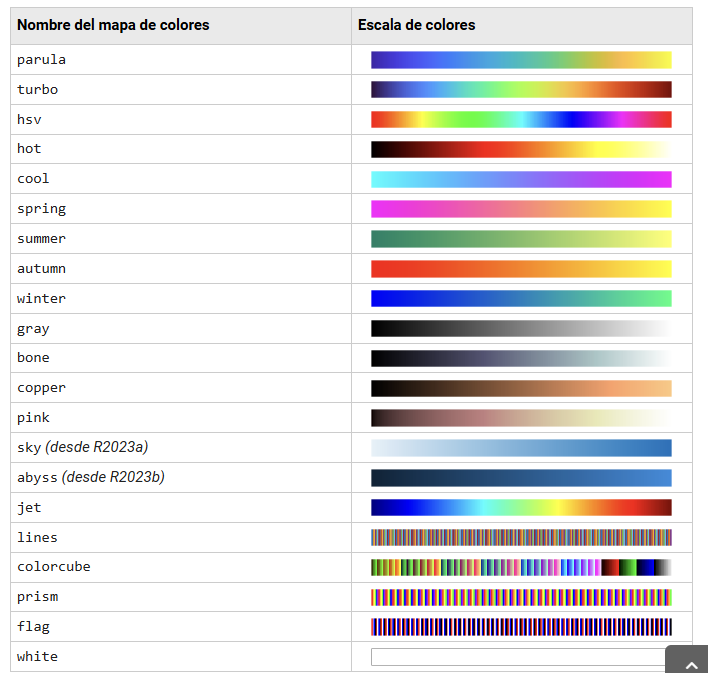

colormap(hot)  % paleta de colores 'hot'

- El comando `colorbar` añade una barra de color al gráfico, que muestra cómo los colores corresponden a los valores numéricos de la función representada en la superficie.

colorbar  % barra de colores (escala)

- Para dar transparencia a una figura en MATLAB, se puede ajustar las propiedades de la función` fsurf: FaceAlpha, EdgeColor, etc.`

fsurf(f,[-2 2 -1 1],'EdgeColor','interp')  % represento la superficie en [-2, 2]x[-1, 1] ocultando las lineas
xlabel('x'), ylabel('y'), zlabel('z')
title('z = x^2 + y^2')
colormap("turbo")

#### Coordenadas polares

Una superficie $$z=f(x,y)$$ será simétrica respecto al eje $$OZ$$ si $$f(x,y) = f(-x,-y)$$. Para representar este tipo de  superficies es más adecuado utilizar como dominio un **círculo centrado en **$$(0,0)$$ en lugar de un rectángulo. Para ello, tendríamos que cambiar nuestro sistema de referencia de coordenadas cartesianas $$(x,y)$$ a polares $$(r, \varphi)$$, donde $$r>0$$ sería la distancia al centro del círculo de un punto proyectado en el plano $$XY$$ y $ $0 \leq \varphi < 2\pi$$ el ángulo polar. Como sabemos, la conversión de cartesianas a polares es

$ $x = r \cos(\varphi)$ , $y = r sen(\varphi)$$.

syms r phi
x = r*cos(phi);
y = r*sin(phi);
z(r,phi) = x^2 + y^2

Obtenemos la forma polar de la función del ejemplo anterior. Ahora podemos representarla utilizando `fsurf`. Es importante recordar que debemos ajustar el rango de valores de las variables, que ahora son $r$ y $\phi$:

fsurf(x,y,z,[0 2 0 2*pi],'EdgeColor','interp','FaceAlpha',0.5) 
xlabel('x'), ylabel('y'), zlabel('z')
title('Superficie en polares')

Compara con las gráficas en coordenadas cartesianas. 

### Curvas de nivel

Para una función$ $z = f(x,y)$$, la **curva de nivel **de valor $$k$$ es el conjunto de todos los pares $$(x,y)\in D$$ tales que su imagen por $$f$$ es el valor $$k$$, es decir $f(x,y) = k$. La función `fcontour` pemite dibujar las curvas de nivel:

Para especificar los niveles de las curvas de nivel en `fcontour`, puedes utilizar la propiedad `LevelList`. Esto te permite definir los valores exactos en los que deseas que aparezcan las curvas de nivel.

fcontour(f,'LevelList',[1 5 10]) % curvas de nivel para k = 1,5,10
grid on
axis equal
xlabel('x'), ylabel('y')

Podemos representar la superficie y las curvas de nivel en una única figura:

syms x y r phi real
f(x,y) = x^2+y^2
x = r*cos(phi);
y = r*sin(phi);
z(r,phi) =f(x,y)
fsurf(x,y,z,[0 2 0 2*pi],'EdgeColor','interp','FaceAlpha',0.5) 
hold on
fcontour(f,'LevelList',[1:4]) % curvas de nivel para k = 1,5,10
colormap("turbo")
grid on
axis equal
xlabel('x'), ylabel('y'), zlabel('z')
title('z = x^2 + y^2')

### Combinación de gráficos

Es posible combinar distintos gráficos en una única figura haciendo uso del comando `subplot(m,n,p)`, que divide la ventana gráfica en una matriz con $$m \times n$$ sistemas de referencia (cada uno con sus respectivos ejes) y selecciona el que ocupa la posición $$p$$ para dibujar sobre él, $$p$ $crece de izquierda a derecha y de arriba a abajo.

**Ejemplo**: Abrimos una nueva ventana gráfica y divídela en dos mitades. En la mitad de la derecha dibuja la superficie $$z=sen(x)+\cos(y)$$ en el dominio $$[0, 5] \times [0, 10]$$. En la de la izquierda, dibuja las curvas de nivel. 

clearvars
close all
syms x y real
z(x,y) = sin(x) + cos(y);
figure
subplot(1, 2, 1)  % mitad izquierda de la figura (m = 1 fila,  n = 2 columnas, posición p = 1) 
fsurf(z,[0 5 0 10],'EdgeColor','interp','FaceAlpha',0.5)
colormap('spring')
xlabel('x'), ylabel('y'), zlabel('z')

title('Superficie')

subplot(1, 2, 2)  % mitad derecha de la figura (m = 1 fila,  n = 2 columnas, posición p = 1) 
fcontour(z,[0 5 0 10])  
colorbar
xlabel('x'), ylabel('y')
title('Curvas de nivel')

### Derivadas parciales

Para calcular derivadas parciales de una función de varias variables:

donde:

- `f`: La función simbólica de la cual se desea calcular la derivada.

- `var`: La variable respecto a la cual se tomará la derivada parcial.

**Ejemplo**: Dada la función $$f(x,y)=\frac{e^x}{sen(y)}$$, calcula $$\frac{\partial f}{\partial x}$, $\frac{\partial f}{\partial y}$, $\frac{\partial^2 f}{\partial x^2}$, $\frac{\partial^2 f}{\partial y^2}$ y $\frac{\partial^2 f}{\partial x \partial y}$$ en el punto $$P(-3, \frac{\pi}{2})$$. Comprueba que $$\frac{\partial^2 f}{\partial x \partial y}= \frac{\partial^2 f}{\partial y \partial x}$$.

syms x y real 
f(x,y) = exp(x)/sin(y);  % funcion a derivar

1. Primeras derivadas parciales:

fx(x,y) = diff(f, 1, x)  % primera derivada parcial con respecto a 'x'

El el punto $$P(-3, \frac{\pi}{2})$$:

fx_P = fx(-3, pi/2)

Con respecto a y:

fy(x,y) = diff(f, y) % con respecto a 'y'
fy_P = fy(-3, pi/2)

2. Segundas derivadas:

fxx(x,y) = diff(f, 2, x)   % segundas derivadas
fxx_P = fxx(-3, pi/2)

fyy(x,y) = diff(f, 2, y)  
fyy_P = subs(fyy, [x, y], [-3, pi/2]) % es lo mismo que fyy(-3, pi/2)

Para las derivadas cruzadas tenemos que usar lo siguiente: $$\frac{\partial^2 f}{\partial x \partial y} = \frac{\partial }{ \partial y}\left( \frac{\partial f}{ \partial x}\right)$$

fxy(x,y) = diff(diff(f, x), y)  % derivada cruzada
fxy_P = fxy(-3, pi/2)

O directamente :

fxy(x,y) = diff(f,x,y) % derivamos con respecto a x,  luego con respecto a y.
fyx(x,y) = diff(f,y,x)

Para comprobar que $$\frac{\partial^2 f}{\partial x \partial y}= \frac{\partial^2 f}{\partial y \partial x}$$:

simplify(fxy== fyx)  % igualdad derivadas cruzadas

`symtrue` significa que la expresión es cierta.

### Ejercicios propuestos

1. Abre una nueva ventana gráfica y divídela en dos mitades. En la mitad superior dibuja la superficie$ $z=2\pi - x^2 + y^2$$ en el dominio $$x=[-5, 5] \times y=[-4, 4]$$.  A continuación, convierte esa superficie a coordenadas polares y represéntala, en la mitad inferior, en el dominio $$r=[0,5] \times \theta=[0, 2\pi]$$.

% escribe aquí el código:




Solución:

soluciones(1)

2. Representa las siguientes funciones de dos variables:

- 
$$$z = \frac{x}{2}^2 + \frac{y}{3}^2$ en $[-3,3] \times [-3,3]$$$


- 
$$$z = \frac{sen(x^2 + y^2)}{x^2 + y^2}$ en $[-3,3] \times [-3,3]$$$


- 
$$$z = \frac{\log(x^2 + y^2)}{x^2 + y^2 -1}$ en $[-1.5, \,1.5] \times[-1.5, \,1.5]$$$


¿Cuál es su dominio? 

%escribe aquí el código





Solución:

soluciones(2)

3. Considera la función  $$z = \frac{x}{2}^2 + \frac{y}{3}^2$$. Comprueba si es simétrica respecto al eje $$OZ$$. En caso de serlo, abre una ventana gráfica y divídela en dos mitades. En la mitad izquierda, representa $$z$$ en coordenadas polares sobre el dominio $$r=[0, 4] \times \varphi = [0, 2\pi]$$. En la derecha, dibuja las curvas de nivel.

%escribe aquí el código




Solución:

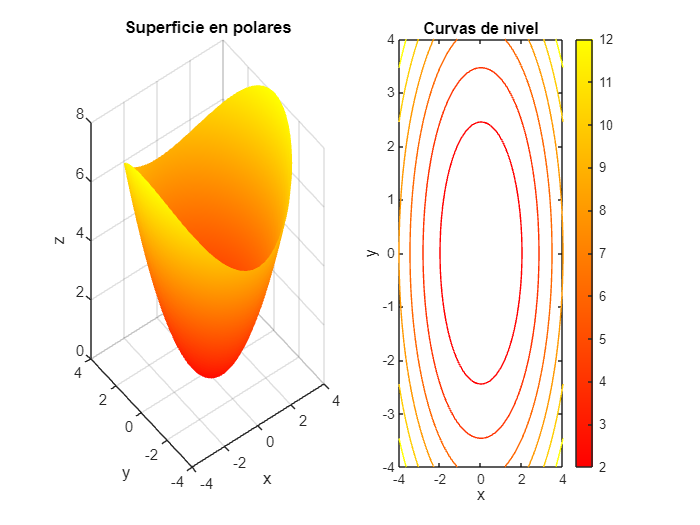

soluciones(3)

4. Calcula las siguientes derivadas parciales:

- $ $\frac{\partial f}{\partial x}$, $\frac{\partial f}{\partial y}$ y $\frac{\partial f}{\partial z}$ $en el punto$ $P(1,-1,1)$$, siendo $$f=\frac{x}{yz}$$.

- $ $\frac{\partial z}{\partial x}$ y $\frac{\partial z}{\partial y}$$ en el punto $$P(0,1,-2)$$, siendo $$F=e^x sen(y+z)-z=0$$ (Utiliza la derivación implícita).

- 
$$ $\frac{df}{dt}$ en $t=\pi$, siendo $f=xyz$, con $x=t^2$, $y=2t$ y $z=e^{-t}$$$


% escribe aquí el código:
clearvars
close all




Solución:

soluciones(4)


f(x,y,z) = x/(y*z):
f_x(P) = -1.00, f_y(P) = -1.00, f_z(P) = 1.00

F(x,y,z) = exp(x)*sin(y + z) - z:
z_x(P) = -1.83, z_y(P) = 1.18

f(t) = 2*t^3*exp(-t):
df(P) = -0.12


### Resumen

**Superficies:**

- [`fsurf(f, [xmin xmax ymin ymax])`](https://es.mathworks.com/help/symbolic/fsurf.html): graficar superficies tridimensionales.

- [`colormap`](https://es.mathworks.com/help/matlab/ref/colormap.html): Permite modificar la paleta de colores utilizada para representar los valores de la función en la superficie. MATLAB ofrece varias paletas de colores, como `parula`, `jet`, `hsv`, `hot`, entre otras.

- [`colorbar`](https://es.mathworks.com/help/matlab/ref/colorbar.html): Añade una barra de color al gráfico que muestra cómo los colores corresponden a los valores numéricos de la función representada en la superficie.

- `FaceAlpha`: Ajusta la transparencia de la superficie. Permite controlar el nivel de opacidad de la figura.

- **Conversión a Coordenadas Polares**: Para representar superficies simétricas respecto al eje, se puede utilizar coordenadas polares:$ x = r \cos(\varphi),  y = r \sin(\varphi)$

**Curvas de Nivel**

- [`fcontour(f,[xmin xmax ymin ymax])`](https://es.mathworks.com/help/symbolic/fcontour.html): dibujar curvas de nivel de una función.

- Utilizando la propiedad `LevelList`, se pueden definir los valores específicos en los que se desea que aparezcan las curvas de nivel.

**Combinación de Gráficos**

- [`subplot(num_filas, num_columnas, posicion)`](https://es.mathworks.com/help/matlab/ref/subplot.html): Permite combinar distintos gráficos en una única figura dividiendo la ventana gráfica en una matriz de subgráficas, `posicion` crece de izquierda a derecha y de arriba a abajo

**Derivadas Parciales**

- [`diff(f, var)`](https://es.mathworks.com/help/symbolic/diff.html): Calcula la derivada parcial de la función simbólica `f` respecto a la variable `var`. 

- `diff(f, var1, var2): `para calcular las derivadas cruzadas.

### Soluciones 

function [] = soluciones(n)
switch n
    case 1
        close all
        syms x y real
        f(x,y) = 2*pi -x^2 + y^2;
        figure
        subplot(2, 1, 1)  % mitad superior
        fsurf(f,[-5 5 -4 4],'EdgeColor','interp')
        xlabel('x'), ylabel('y'), zlabel('z')
        colorbar
        title('Superficie en cartesianas')

        syms r phi
        x = r*cos(phi);
        y = r*sin(phi);
        z(r,phi) = f(x,y);

        subplot(2, 1, 2)
        fsurf(x,y,z,[0 5 0 2*pi],'EdgeColor','interp')  % mitad inferior: superficie en polares
        xlabel('x'), ylabel('y'), zlabel('z')
        colorbar
        title('Superficie en polares')
    case 2
        syms x y real
        z = x^2/2 + y^2/3
        fsurf(z,[-3 3 -3 3],'EdgeColor','interp','FaceAlpha',0.5)
        colormap('spring')
        xlabel('x'), ylabel('y'), zlabel('z')
        fprintf('El dominio es R2.\n')
        title('x^2/2 + y^2/3')

        z = sin(x^2+ y^2)/(x^2+y^2)
        fsurf(z,[-3 3 -3 3],'EdgeColor','interp','FaceAlpha',0.5)
        colormap('jet')
        xlabel('x'), ylabel('y'), zlabel('z')
        title('sin(x^2+ y^2)/(x^2+y^2)')
        fprintf('El dominio es R2-{(0,0}).\n')

        z =log(x^2+y^2)/(x^2+y^2-1)
        fsurf(z,[-3/2 3/2 -3/2 3/2],'EdgeColor','interp','FaceAlpha',0.5)
        colormap('autumn')
        xlabel('x'), ylabel('y'), zlabel('z')
        title('log(x^2+y^2)/(x^2+y^2-1)')
        fprintf('El dominio es R2-{(0,0), (x,y): x^2+y^2 = 1}.\n')
    case 3
        syms x y r phi real
        f(x,y) = x^2/2 + y^2/3;
        x = r*cos(phi);
        y = r*sin(phi);
        z(r,phi) = f(x,y);
        subplot(1, 2, 1)
        fsurf(x,y,z,[0 4 0 2*pi],'EdgeColor','interp')  % mitad inferior: superficie en polares
        xlabel('x'), ylabel('y'), zlabel('z')

        title('Superficie en polares')
        subplot(1, 2, 2)
        fcontour(f,[-4 4 -4 4])
        colorbar
        xlabel('x'), ylabel('y')
        title('Curvas de nivel')
    case 4
         syms x y z real
        f(x,y,z) = x/(y*z);
        fx = diff(f,x);
        fy = diff(f,y);
        fz = diff(f,z);
        fx_P = double(fx(1,-1,1));
        fy_P = double(fy(1,-1,1));
        fz_P = double(fz(1,-1,1));
        fprintf("\nf(x,y,z) = %s:\nf_x(P) = %.2f, f_y(P) = %.2f, f_z(P) = %.2f\n", char(f),fx_P, fy_P, fz_P)
        F(x,y,z) = exp(x)*sin(y+z)-z;
        zx = -diff(F,x)/diff(F,z);
        zy = -diff(F,y)/diff(F,z);
        zx_P = double(zx(0,1,-2));
        zy_P = double(zy(0,1,-2));
        fprintf("\nF(x,y,z) = %s:\nz_x(P) = %.2f, z_y(P) = %.2f\n", char(F),zx_P, zy_P)
        syms t real
        x = t^2; y = 2*t; z = exp(-t);
        f = x*y*z;
        ft(t) = diff(f,t);
        ft_P = ft(pi);
        fprintf("\nf(t) = %s:\ndf(P) = %.2f\n", char(f),ft_P)
end

end